# Example 6.28: Classification of Flow Cytometry Data (Case II)

Note: this script complements Example 6.28 (Section 6.7.2) of **Statistics for Chemical Engineers**: the CNN classification for the second case of endotoxin data. Victor Z UW-Madison, 2020 use CNN for clasifying flow cytometry fields (case II)

clc; clear all; close all hidden;

digitDatasetPath = [pwd,'/Data/Endotoxins_CaseII/Gray'];

imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

n=length(imds.Labels);

## Data

shuffle images to randomize

rng(0)
imds = shuffle(imds);

% select only a subset to accelerate
indices = 1:n;
imds = subset(imds,indices);

% count number of points with each label

labelCount = countEachLabel(imds)

labelCount = 3×2 table
    Label    Count
    _____    _____
     EC       24  
     PA       28  
     SM       32  
	Get insights using Copilot


% determine size of images
img = readimage(imds,1);
siz=size(img)

siz =     50    50



% creare training and validation sets
numTrainFiles = 15; % number of files in each label
rng(0);
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## CNN

define CNN architecture

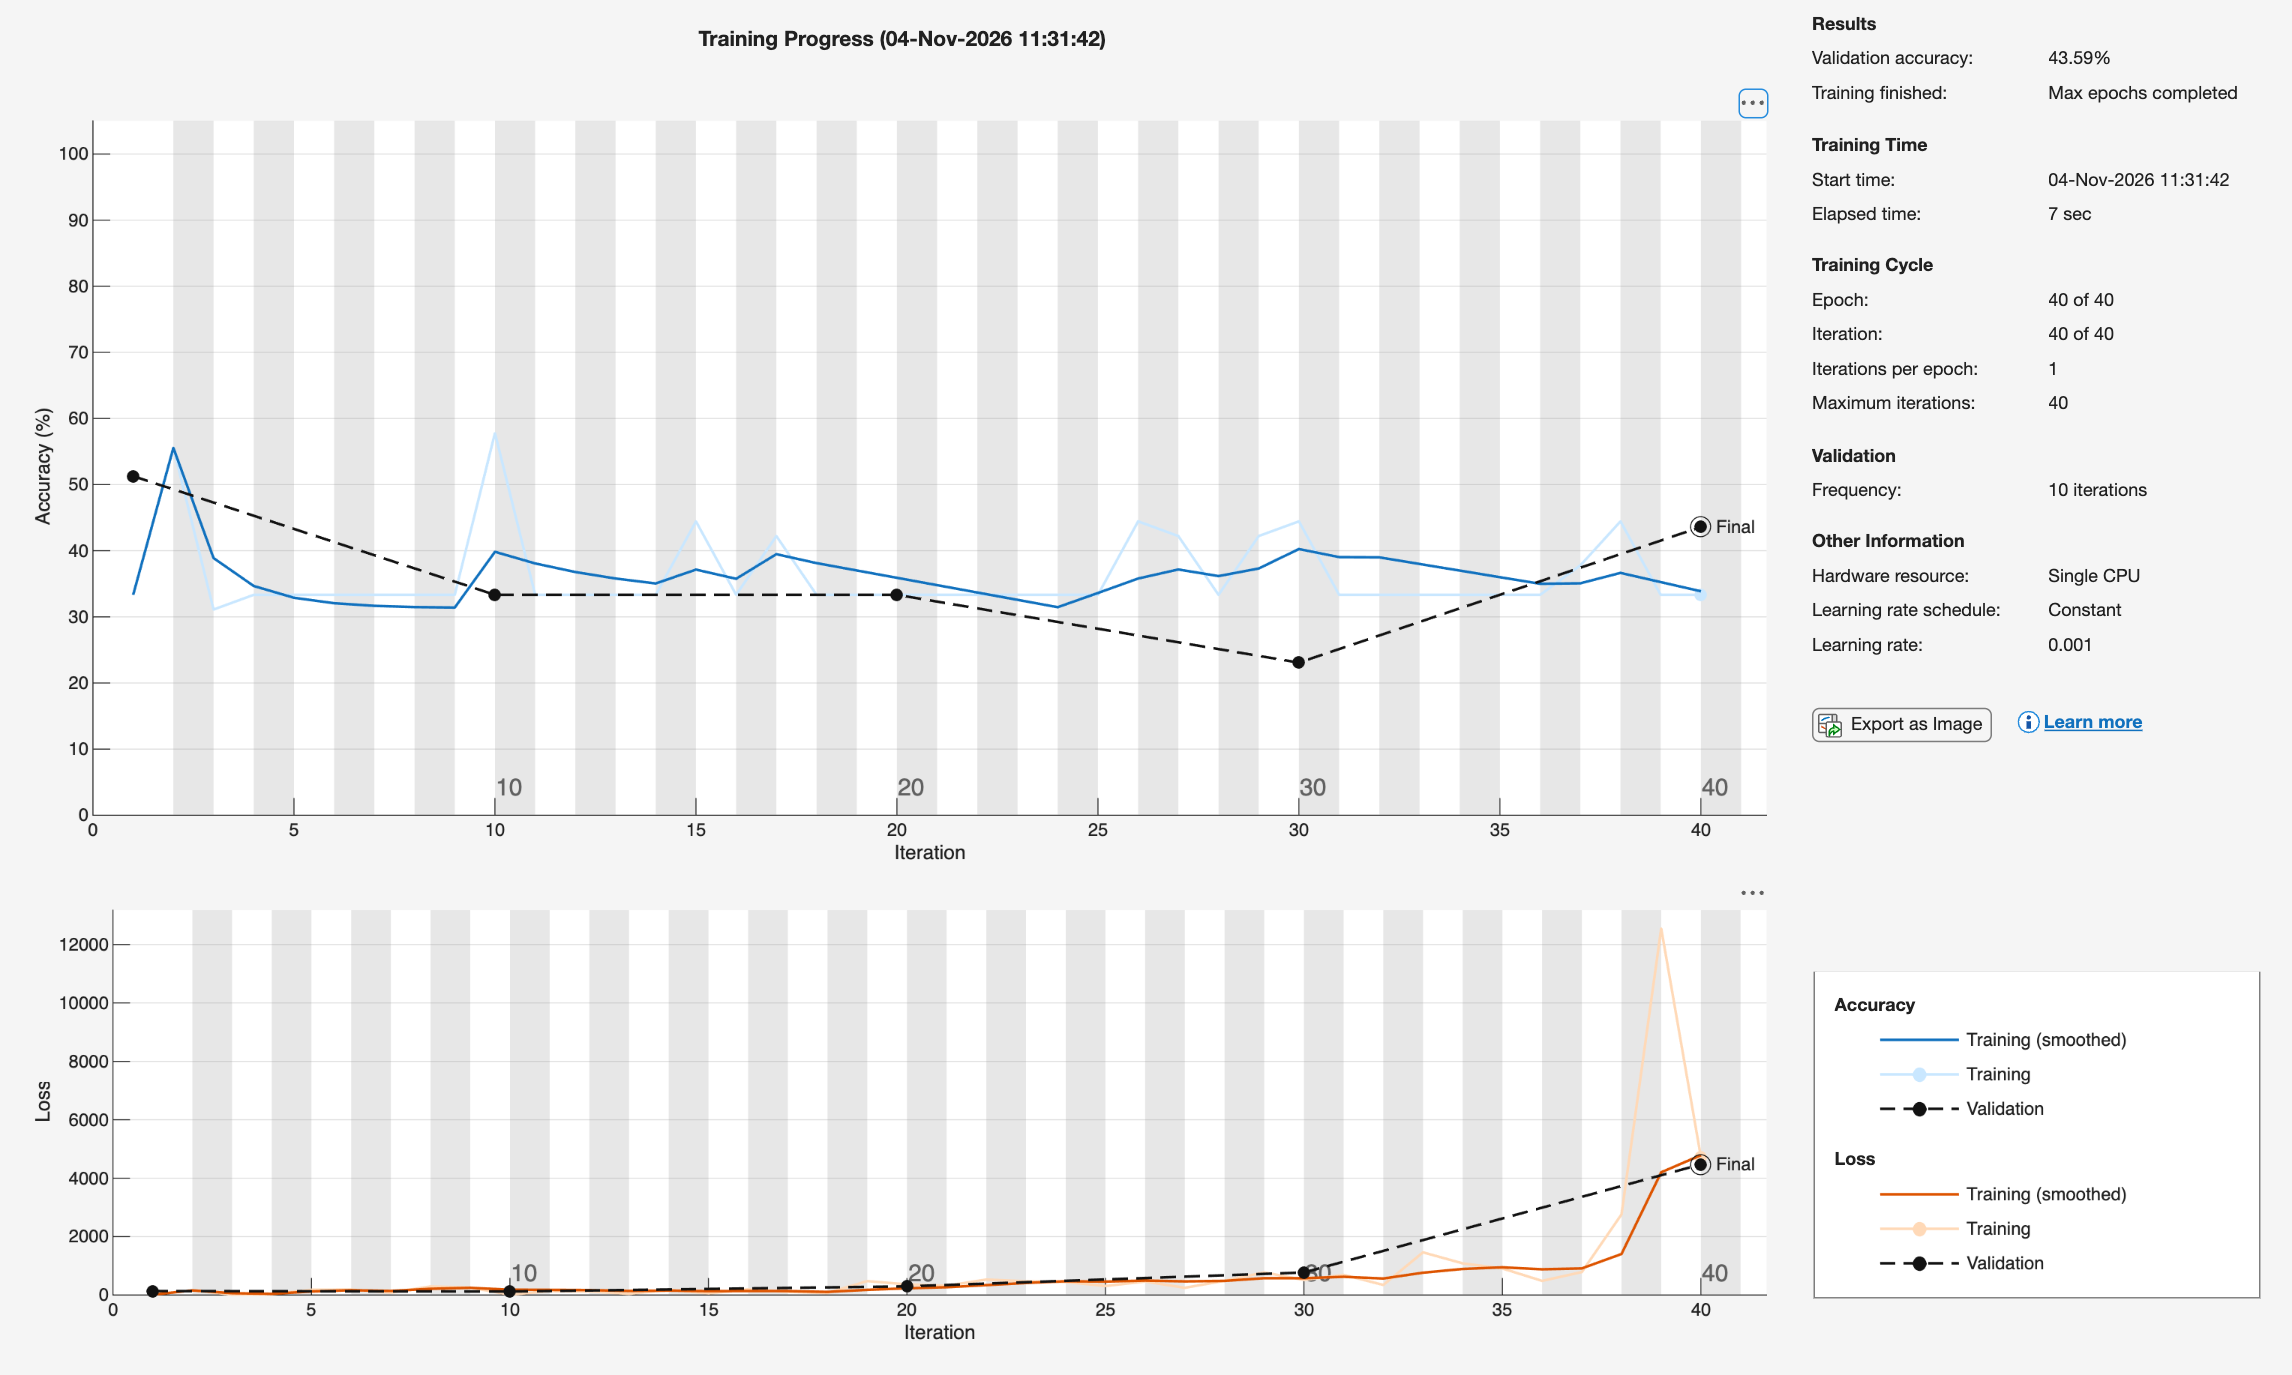

layers = [
    imageInputLayer([50 50 1]) % height, width, and channel size
    
    convolution2dLayer(3,2,'Padding','same')
    reluLayer
    
    fullyConnectedLayer(3) % fully connected layer has 2 classes
    softmaxLayer
    classificationLayer
    ];

% train CNN

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs',40, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',10, ...
    'Verbose',false, ...
    'Plots','training-progress');

net = trainNetwork(imdsTrain,layers,options);


% display architecture
% analyzeNetwork(net)

## Accuracy and confusion matrices

obtain training accuracy

YPredT = classify(net,imdsTrain);
YTrain = imdsTrain.Labels;
accuracy = sum(YPredT == YTrain)/numel(YTrain)

accuracy = 0.3333


% confusion matrix
figure(2)
subplot(2,2,1)
ConfusionTrain = confusionchart(YTrain,YPredT,'DiagonalColor',[1 1 1],'OffDiagonalColor',[0,0,0]);
xlabel('Predicted')
ylabel('True')

% obtain validation accuracy
YPredV = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPredV == YValidation)/numel(YValidation)

accuracy = 0.4359

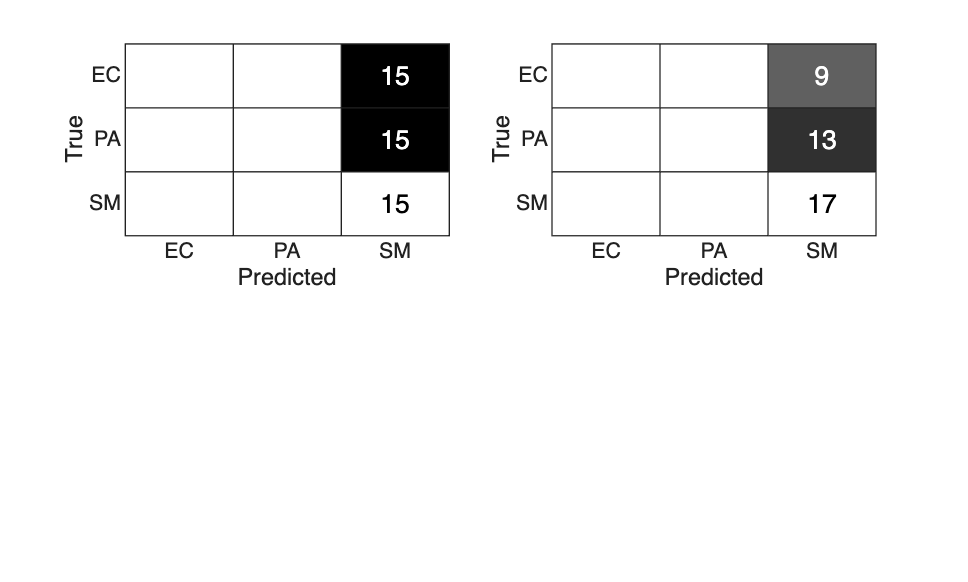


% confusion matrix
figure(2)
subplot(2,2,2)
ConfusionTrain = confusionchart(YValidation,YPredV,'DiagonalColor',[1 1 1],'OffDiagonalColor',[0,0,0]);
xlabel('Predicted')
ylabel('True')
print -depsc ch6_endotoxins_confusion_caseII.eps


% display filters
net.Layers(2).Weights

ans = 3×3×1×2 single array
ans(:,:,1,1) =
    0.4995    2.1564    1.2928
    0.8083    1.0023    0.7242
    0.7868    0.2029    0.0627
ans(:,:,1,2) =
   -0.8984    1.6206    1.1729
    1.0732    1.1522    0.9134
    1.0917    1.2447    0.9702

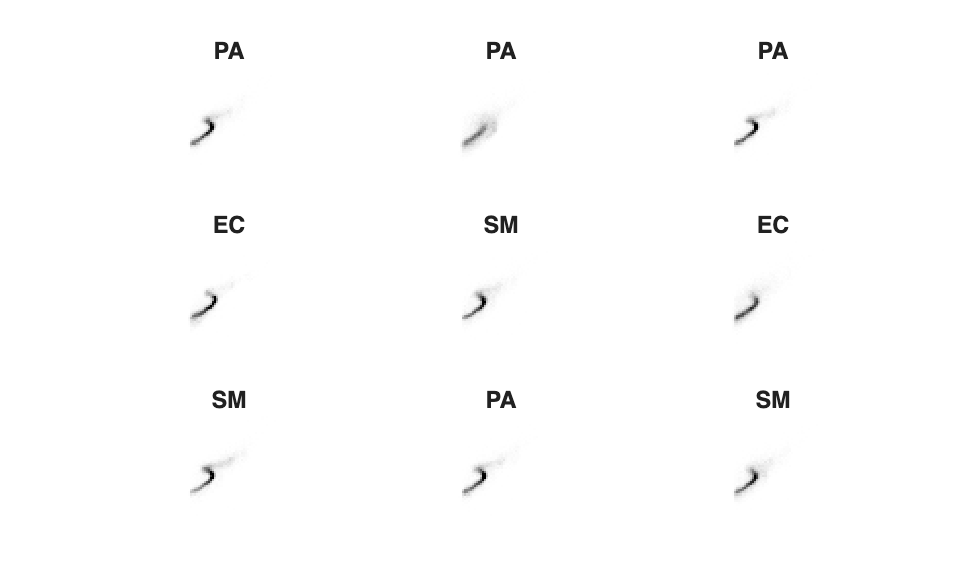


% Display some of the images in the datastore.

figure(1)
for i = 1:9
    subplot(3,3,i);
    imshow(imdsValidation.Files{i});
    title(imdsValidation.Labels(i))
end
print -depsc ch6_endotoxins_data_caseII.eps

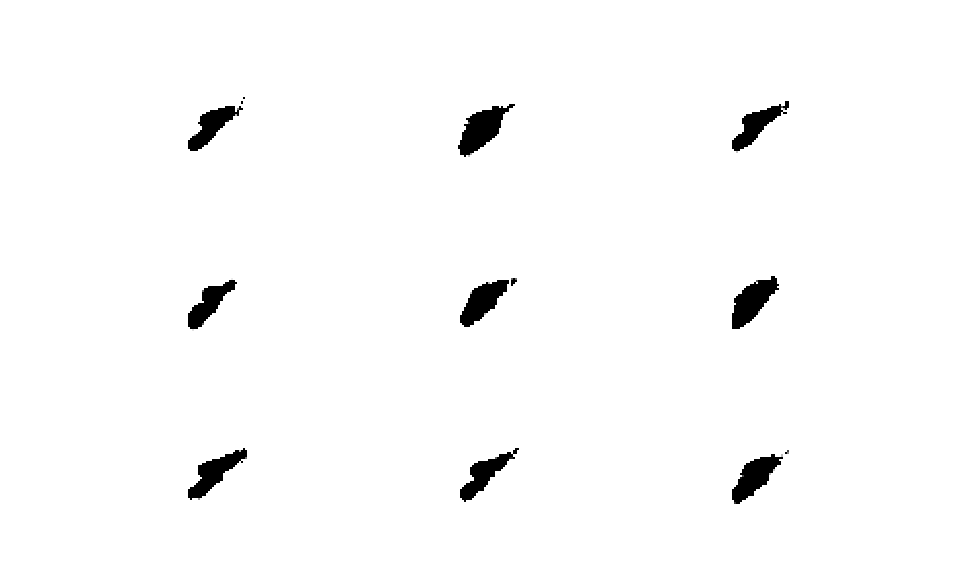


% get activations
Act = activations(net,imdsValidation,2);

figure(3)
for i=1:9
    subplot(3,3,i)
    imshow(Act(:,:,1,i))
end
print -depsc ch6_endotoxins_activations_caseII.eps

## Note

Compare the accuracy with Case I: the harder the classes are to tell apart, the lower the accuracy.